clc; clear; close all
%You can use trapezoid and Simpsons rules for plotting the conversion and rate curves
% Use the same technique for question 24f.
%If you have issues with them methods please use excel
x = [0,0.2,0.4,0.6,0.8,0.965];
y = [60,31,19.2,19.2,29.1,60];
% Just showing you how to use slidder, change value and see what happens
volumediffential = 0.576

volumediffential =                      0.576


rA = (y./2).^-1;
x1 = linspace(0,1);
% polynomial fitting
p = polyfit(x,y,length(y)-1);

% for loop for the polynomial creation
initial= 0;
for i = 1:length(y)
syms x_var
k = p(i);
f(i) = symfun(k.*x_var.^(length(y)-i),x_var);
Fun = sum(f);
abc = matlabFunction(Fun);
end
%evaluating yur polynomial
f_poly = polyval(p,x1);
abc;

% for loop for integral
size=linspace(0,0.965);
for i=1:100
V(i)=integral(abc,0,size(i));
end

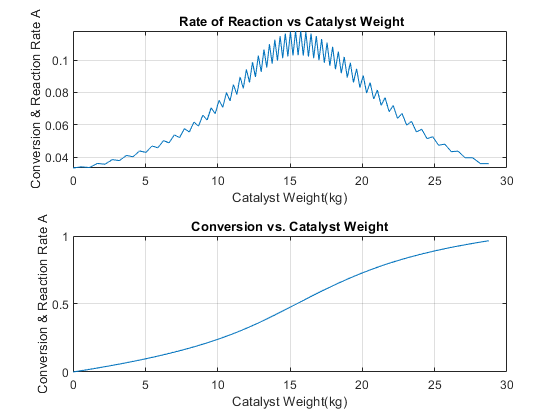

rate = rA(1);
h = 0.0097;
range = linspace(0,0.965);
for i=1:100
syms var
rate;
volumediffential;
h;
lhs = symfun(((((volumediffential)./2).*(2./h))-(1./rate(i)))-1./var,var);
newrate = matlabFunction(lhs);
rateguess = rate(i) + 0.001;
OutputrA = fzero(newrate, rateguess);
z=i+1;
% if conditions
if z < 100
rate(z) = OutputrA;
volumediffential = V(z)-V(z-1);
h = range(z+1)-range(z);
else
rate(100) = OutputrA;
hold off

plot(V,rate)
grid on
title(' Rate of Reaction vs Catalyst Weight')
xlabel('Catalyst Weight(kg)')
ylabel('Conversion & Reaction Rate A')

nexttile
plot(V,size)
grid on
title('Conversion vs. Catalyst Weight')
xlabel('Catalyst Weight(kg)')
ylabel('Conversion & Reaction Rate A')


end
end